# FIR Filter Design

The following example will demonstrate pronciples of FIR filter design using frequency sampling and windowing.

Determine desired continuous cutoff frequency and show filters' magnitude frequency response. 

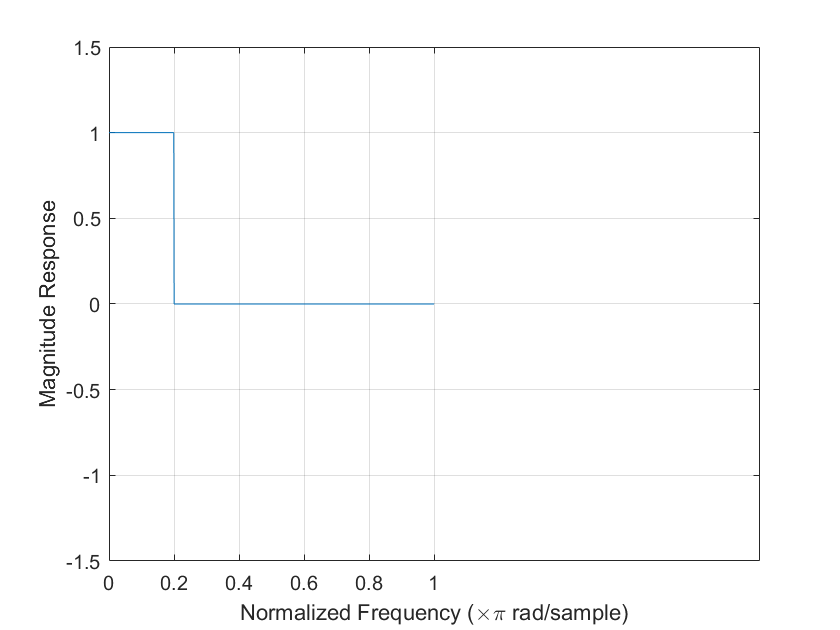

f0=0.2;
fc=0:1/1000:1-1/1000;
Hc=(fc<f0);
plot(fc,Hc);
axis([0 2 -1.5 1.5]);
ax = gca;
ax.XTick = 0:.2:1;
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude Response')

Use frequency sampling with number of samples ***L*** equal to number of numerator coefficients ***b*** to produce samples of amplitude frequency response.

Keep in mind symmetrical frequency response of a digital filter above the Nyquist frequency. 

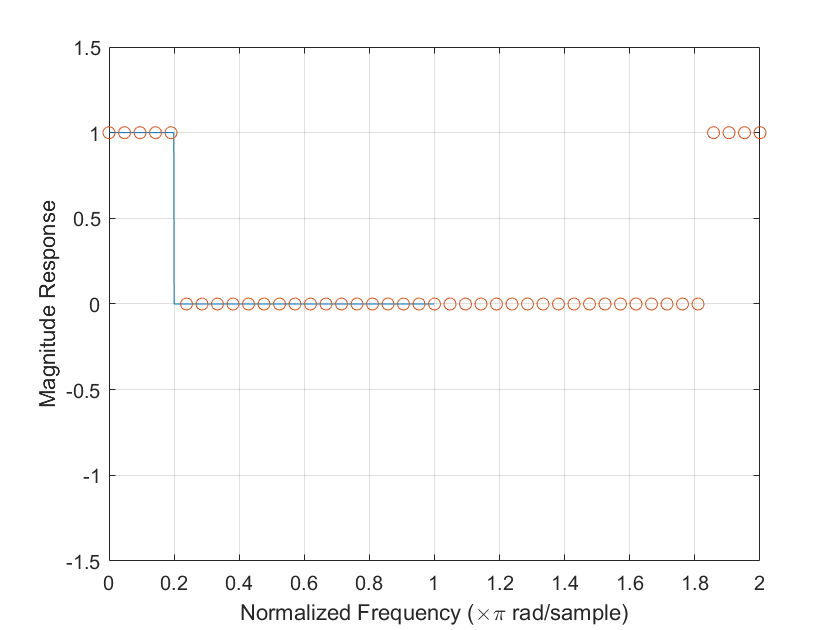

L=43;
pass = fix(f0*L/2)+1;
if rem (L,2) == 0
    s = -1; 
else 
    s = 1; 
end
Ha = [ones(1,pass), zeros(1,L-2*pass+1), s*ones(1, pass-1)];
f=2*(0:L-1)/(L-1);
plot(fc, Hc, '-', f,Ha,'o');
axis([0 2 -1.5 1.5]);
ax = gca;
ax.XTick = 0:.2:2;
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude Response')

Determine linear phase response of a causal FIR filter. 

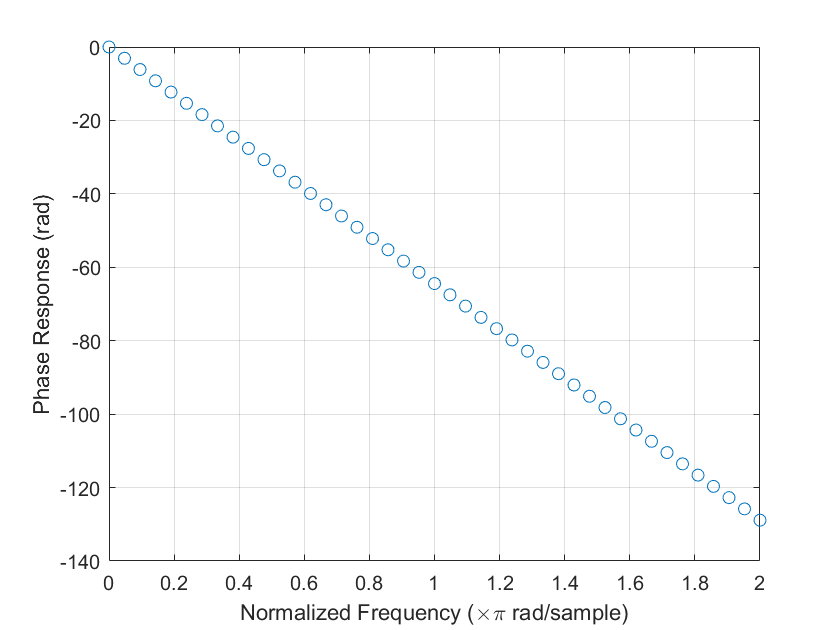

M = (L-1)/2;
k = (0:L-1);
Hp = 2*pi*(-M)*k/L;
plot(f,Hp,'o');
ax = gca;
ax.XTick = 0:.2:2;
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase Response (rad)')

Compose complex filter response and use inverse discrete Fourier transform to obtain filters' impulse response. 

Remove imaginary part appearing due to numerical errors. 

Numerator coefficients b are equal to FIR filters' impulse response. 

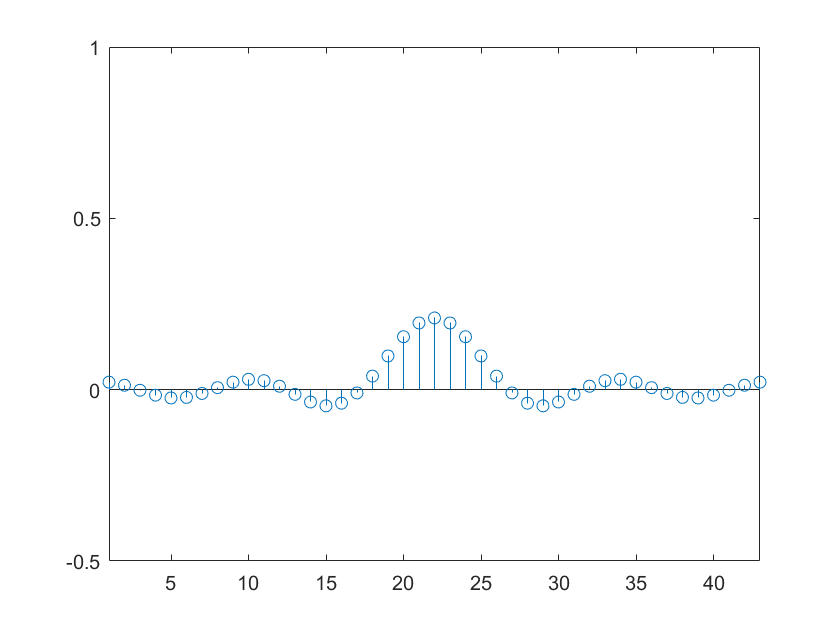

H=Ha.*exp(1i*Hp);
h=real(ifft(H));
b=h;
stem(h);
axis([1 L -0.5 1])

Show continuous frequency response of the designed filter.

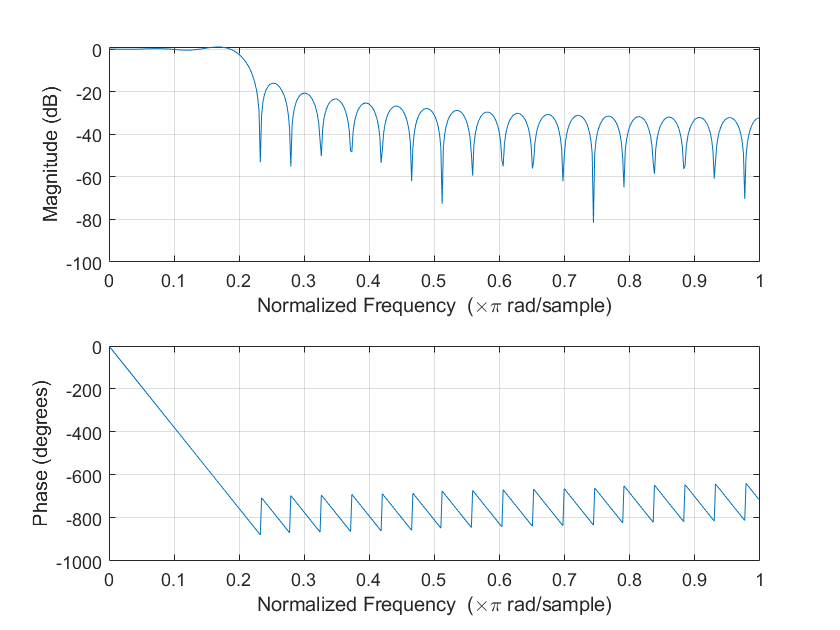

freqz(b,1);

Show zeros in Z plane.

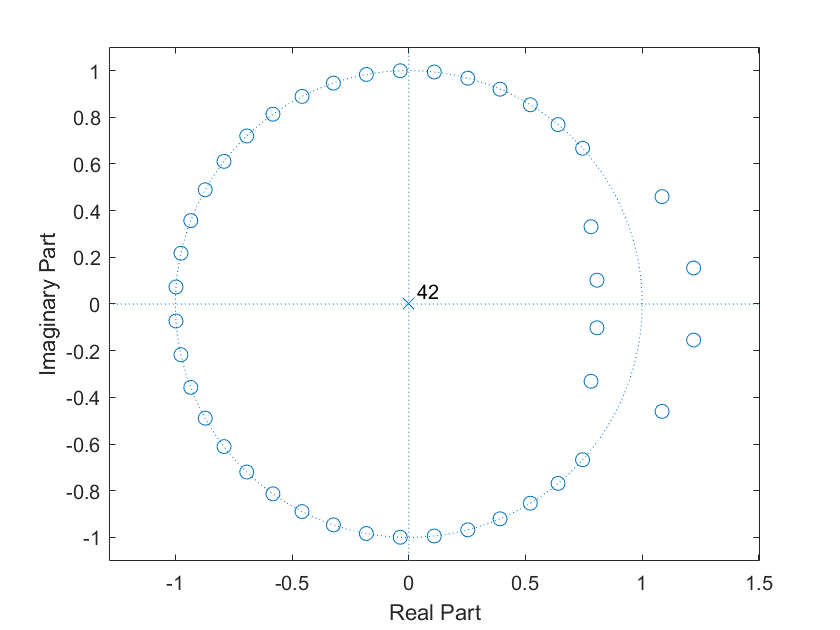

zplane(b,1)

Improve results by use of windowing functions.

Neutral window is rectangular.

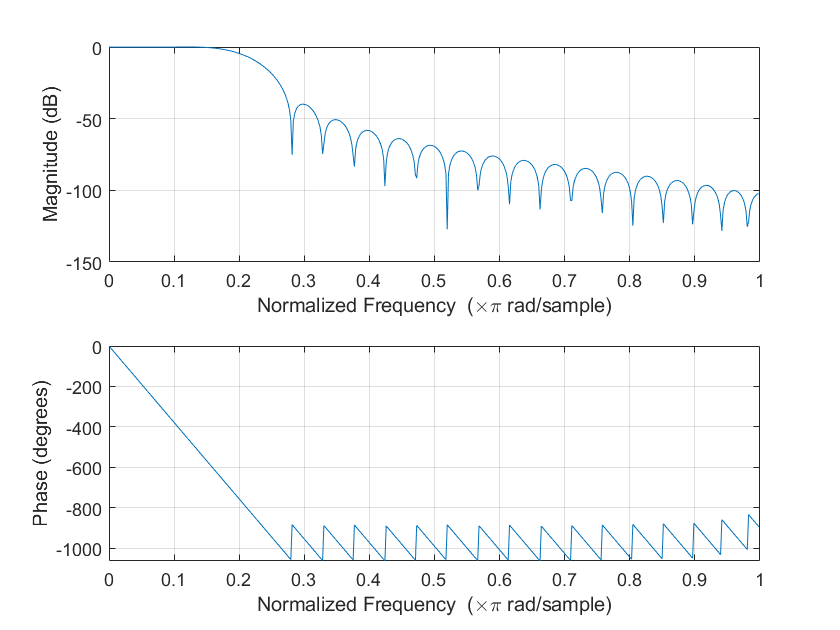

window="hann";
eval(strcat("bw=b.*",window,"(L)';"));
freqz(bw,1);

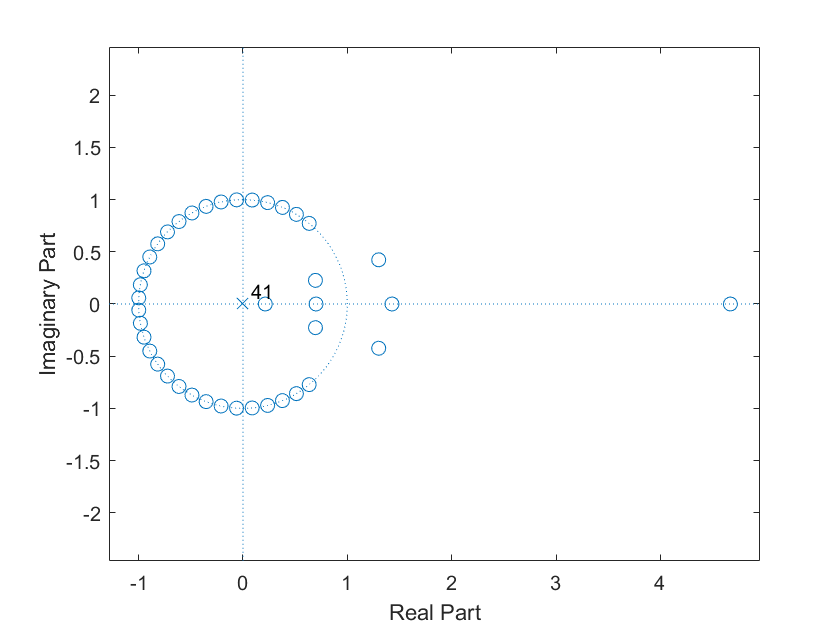

zplane(bw,1)

return;

Now play the 'noisy' 500Hz music.

x=audioread("handel_500.wav");
y=filter(b,1,x);

p1=audioplayer(x,fs);
play(p1)
 

p2=audioplayer(y,fs);
play(p2)
 